# Geshgorin

Il primo teorema afferma che in una matrice quadrata complessa, gli autovalori della matrice appartengono tutti all'unione dei dischi $D_k$

Ogni disco è definito come $\left\lbrace z\in \mathbb{C}:|z-A_{\mathrm{kk}} |\le \;r_k \right\rbrace$, con $A_{\mathrm{kk}}$ elemento k-esimo della diagonale principale ed $r_k$ raggio del disco $D_k$, calcolato sommando i restanti elementi della k-esima riga.

format short

N = 5;
A = complex(rand(N, N), rand(N, N));

centri = zeros(N, 1);
raggi  = zeros(N, 1);
for k = 1 : N
    centri(k) = A(k,k);
    raggi(k) = sum(abs(A(k,:))) - abs(centri(k));
end

dischi = table(centri, raggi)  % Tabella per comodità di visualizzazione

dischi = 5×2 table
          centri          raggi 
    __________________    ______
      0.90199+0.43655i    1.8721
      0.54011+0.84137i     2.706
    0.0093325+0.53679i    3.1859
      0.45497+0.16157i    3.7715
      0.43666+0.17898i    3.1032

minimo  = min(centri - raggi);
massimo = max(centri + raggi);

## Plottare i cerchi

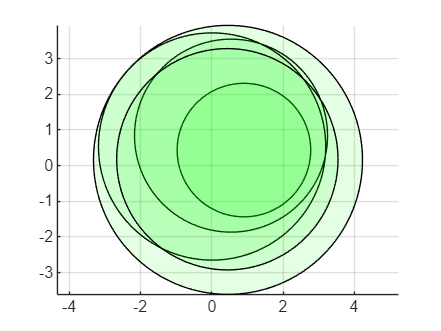


for k = 1:N
    cerchio(real(centri(k)), imag(centri(k)), raggi(k))
    hold on
end
grid on
axis equal
hold off

## Funzioni


function cerchio(x0, y0, r)
    theta = linspace(0, 2*pi, 360);
    x = x0 + r * cos(theta);
    y = y0 + r * sin(theta);
    patch(x, y, "g", "FaceAlpha", .1)
end
